# Group Problem: Active Control Design of a Suspension System 

This live script supports the design of a control system in the frequency domain for a quarter model car's suspension system. Design specifications on position of the car are defined over different frequency ranges. 

Plots include the loop gain and phase (with loop shaping magnitude requirements and margins), closed loop PSD, and an impulse response to simulate a speed bump. 

MAE 3260 Spring 2021

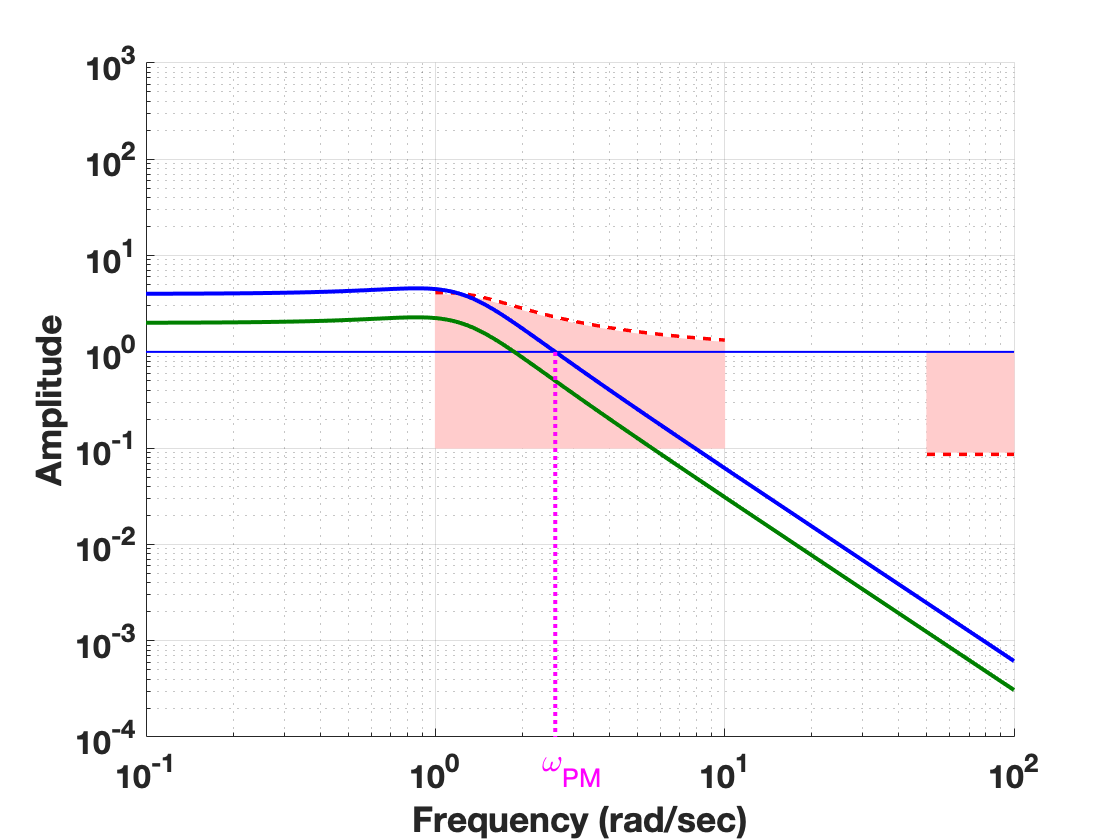

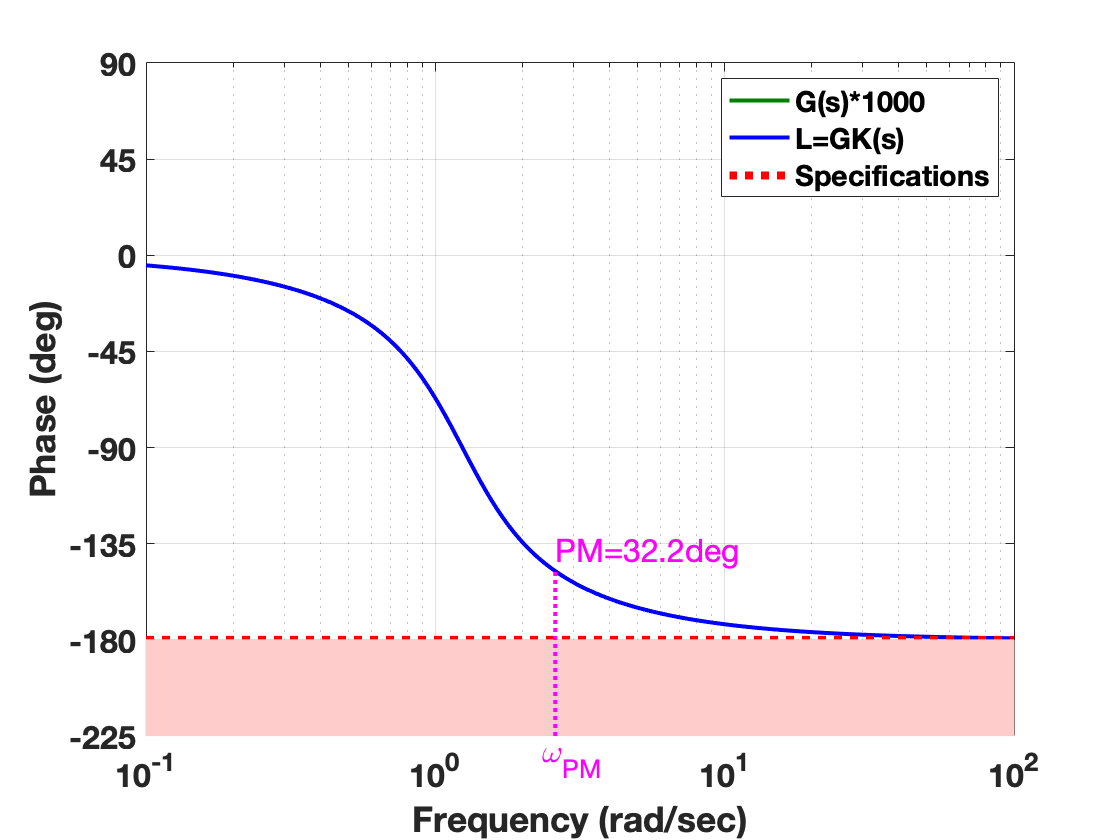

% function to set up nice figures
setupscript;

% User Input: Controller Parameters
% #1: K(s) = Kp
if true
    K.K0=2000; %controller gain
    K.z=[]; %do not change for this problem
    K.p=[]; %do not change for this problem
    K.sensor='position';
end
% #2: K(s) defined using gain, poles and zeroes (position sensor)
if false
    K.K0=2000; %controller gain
    K.z=[-1]; %controller zeroes (e.g. [-1;-10] defines two zeros)
    K.p=[-1;-2]; %controller poles (e.g. [-1;-10] defines two poles)
    K.sensor='position';
end
% #3: K(s) defined using gain, poles and zeroes (accel sensor)
if false
    K.K0=2000; %controller gain
    K.z=[-1]; %controller zeroes (e.g. [-1;-10] defines two zeros)
    K.p=[-1;-2]; %controller poles (e.g. [-1;-10] defines two poles)
    K.sensor='accel';
end
% Form controller
K=formController(K);

% Car and suspension parameters
plant.k = 500; % spring constant (N/m)
plant.m = 325; % 1/4 mass of car (kg)
plant.b = 410; % damper constant (Nsec/m)

% Design specifications
specs.D=0.05;specs.wd1=1;specs.wd2=10; %max PSD for disturbance/road
specs.xmax.D=0.025; %requirement on max x from disturbance/road
specs.N=0.025;specs.wn1=50;specs.wn2=100; %max PSD for sensor noise
specs.xmax.N=0.005; %requirement on max x from noise

% Make plots for control design iteration 
runFreqResponse_Loop(plant,K,specs); %Loop transfer function

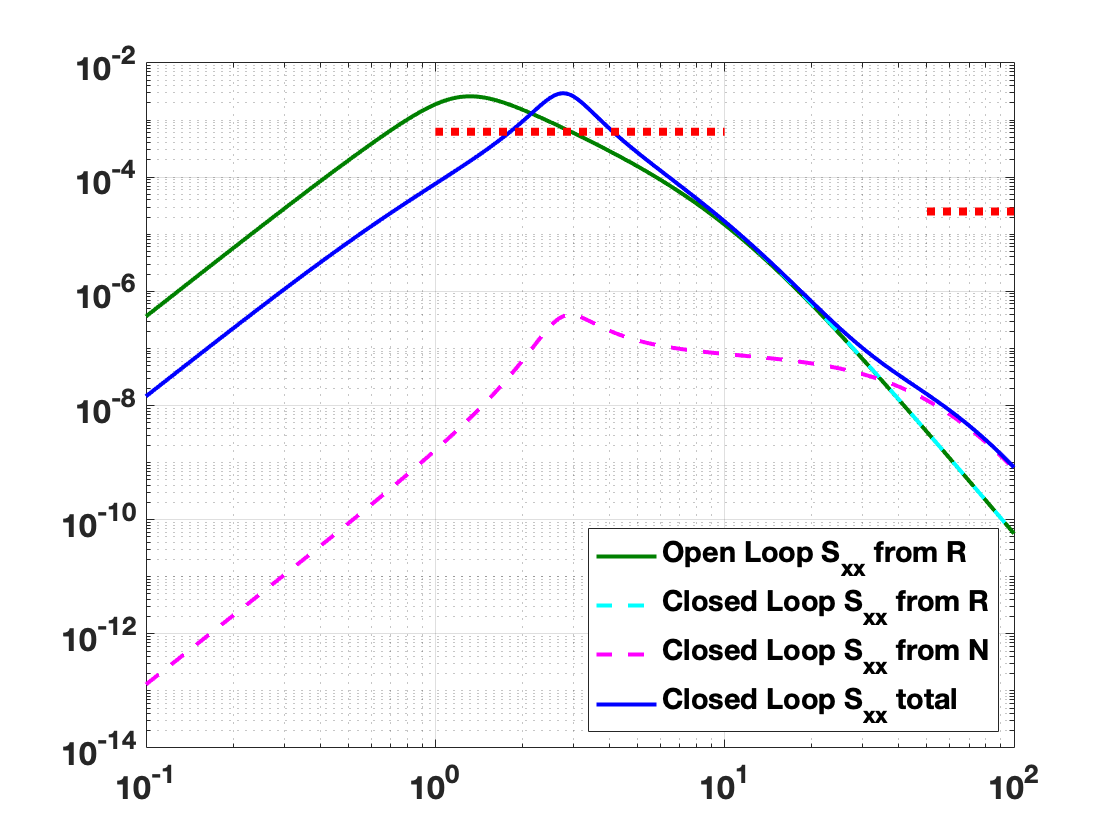

plot_PSDs(plant,K,specs); %Open and Closed loop PSDs

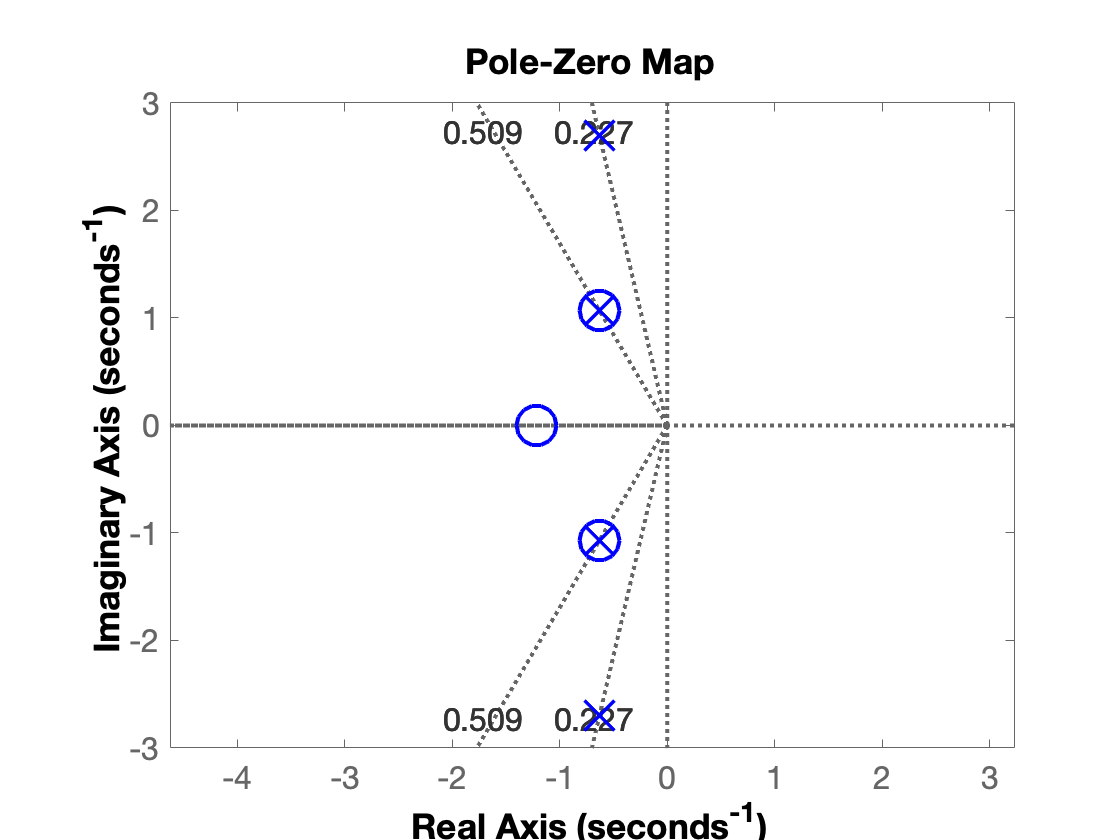

plot_PZmap(plant,K,specs); %Closed loop poles

## For Speed Bump Analysis: Time simulation of an impulse

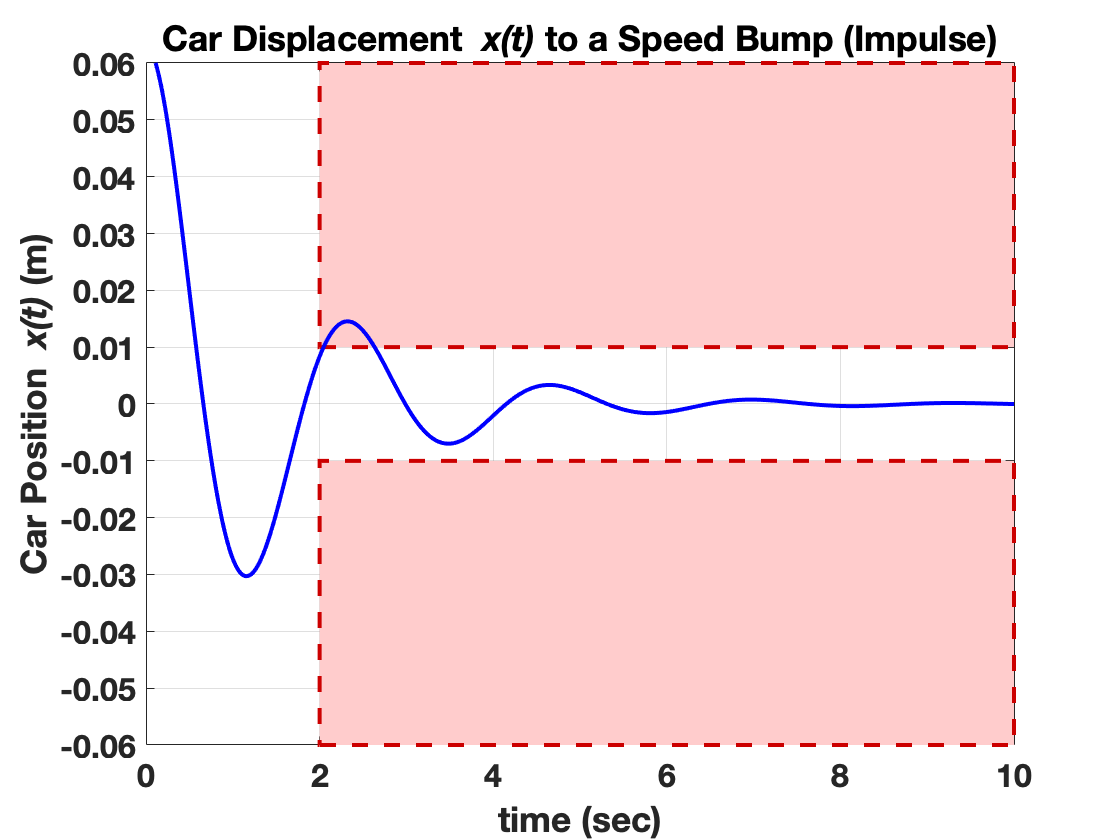

% r(t) = 0.05 delta(t) %5cm speed bump
 
specs.Ri=0.05; %5cm impulse
specs.xmax.I=0.01; %1cm max at time
specs.time=2; %time when the specification must be met
runImpulse_RtoX(plant,K,specs);

## For Verification: Time simulation of a sinusoidal input r(t)

%% FUTURE EXPANSION: not working for this version of groupwork
% r(t) = 0.05 sin (w*t) %5cm sinusoid with frequency w
% you have to specify w and the numerator
 
w=3;
%run_bumpyroad('RtoX',plant,K,specs,w); %options: 'RtoX','RtoA','RtoD'

function runFreqResponse_Loop(plant,K,specs)
%% Frequency Response: Road R to Car Position Y (m)
%
% Plant parameters
m=plant.m;
b=plant.b;
k=plant.k;
den=[m b k];

% Numerator and Denominator coefficients for transfer functions

% Design requirement on Sxx from the road
R=specs.D;wd1=specs.wd1;wd2=specs.wd2;
wd=linspace(wd1,wd2,100); 

Gdr.tf=tf([b k],1);
Gd=freqresp(Gdr.tf,wd);Gd=squeeze(Gd);
Sdd_sqrt=R*abs(Gd);

G_OL.tf=tf([b k],den);
G.tf=tf(1,den);
G.jw=freqresp(G.tf,wd);G.jw=squeeze(G.jw);

xmax.D=specs.xmax.D;
Xrqmt.D=[abs(G.jw).*Sdd_sqrt+xmax.D]/xmax.D;
% fill area on plot
Xd=[wd(1) wd wd(end)];
Yd=[0.1;Xrqmt.D;0.1];

% Design requirement on Sxx from the noise
xmax.N=specs.xmax.N;
N=specs.D;wn1=specs.wn1;wn2=specs.wn2;
wn=linspace(wn1,wn2,100); 
Xrqmt.N=[xmax.N]/[N+xmax.N]*ones(length(wn),1);
% fill area on plot
Xn=[wn(1) wn wn(end)];
Yn=[1;Xrqmt.N;1];

if strcmp(K.sensor,'accel'),
    G.tf=tf([1 0 0],den);
end

%find frequency response for full range
omega=logspace(-1,2,500);
G.jw=freqresp(G.tf,omega);G.jw=squeeze(G.jw);
K.jw=freqresp(K.tf,omega);K.jw=squeeze(K.jw);

L.jw=[G.jw].*[K.jw];
%[Gm,Pm,wGm,wPm]=margin(L);
[Gm,Pm,wGm,wPm]=margin(abs(L.jw(160:end)),angle(L.jw(160:end))*180/pi,omega(160:end));
figure(1);clf
subplot(1,1,1, 'XScale', 'log', 'YScale', 'log')
hold on;
ll2=loglog(wd,Xrqmt.D,'r:','linewidth',4);
loglog(wn,Xrqmt.N,'r:','linewidth',4);
fill(Xd,Yd,[1 0.8 0.8],'EdgeColor',[1 0.8 0.8]);
fill(Xn,Yn,[1 0.8 0.8],'EdgeColor',[1 0.8 0.8]);
loglog(omega([1 end]),1*[1 1],'b-','linewidth',1);
ll=loglog(omega,abs(G.jw)*1000,'g-',omega,abs(L.jw),'b-');
set(ll(1),'color',[0 0.5 0]);
set(gca,'ytick',10.^[-4:1:3]);
axis([omega([1 end]) 10^(-4) 10^3]);
ax=axis;
loglog(wPm*[1;1],[1;ax(3)],'m:');
hold off
text(0.9*wPm,ax(3)*0.5,'\omega_{PM}','color',[1 0 1]);
ylabel('Amplitude');
xlabel('Frequency (rad/sec)');
grid;
figure(2);clf
%subplot(212)
sl=semilogx(omega,angle(G.jw)*180/pi,'g-',omega,angle(L.jw)*180/pi,'b-');
set(sl(1),'color',[0 0.5 0]);
axis([omega([1 end]) -225 90]);
ax=axis;
hold on;
semilogx(omega([1 end]),-180*[1 1],'r:','linewidth',4);
fill(omega([1 1 end end]),[-270 -180 -180 -270],[1 0.8 0.8],'EdgeColor',[1 0.8 0.8]);
semilogx(wPm*[1;1],[ax(3);(-180+Pm)],'m:');
hold off;
legend([sl;ll2],'G(s)*1000','L=GK(s)','Specifications','location','northeast');
text(0.9*wPm,ax(3)-10,'\omega_{PM}','color',[1 0 1]);
text(wPm,(-180+Pm+10),['PM=',num2str(Pm,3),'deg'],'color',[1 0 1]);
ylabel('Phase (deg)');
xlabel('Frequency (rad/sec)');
set(gca,'ytick',[-225:45:90]);
grid

end

function plot_PSDs(plant,K,specs);
%
% Plant parameters
m=plant.m;
b=plant.b;
k=plant.k;
den=[m b k];

% Design requirement on Sxx from the road
R=specs.D;wd1=specs.wd1;wd2=specs.wd2;
wd=linspace(wd1,wd2,100); 

Gdr.tf=tf([b k],1);
Gd=freqresp(Gdr.tf,wd);Gd=squeeze(Gd);
Sdd_sqrt=R*abs(Gd);

G_OL.tf=tf([b k],den);
G.tf=tf(1,den);
G.jw=freqresp(G.tf,wd);G.jw=squeeze(G.jw);

xmax.D=specs.xmax.D;
Xrqmt.D=[abs(G.jw).*Sdd_sqrt+xmax.D]/xmax.D;

% Design requirement on Sxx from the noise
xmax.N=specs.xmax.N;
N=specs.D;wn1=specs.wn1;wn2=specs.wn2;
wn=linspace(wn1,wn2,100); 
Xrqmt.N=[xmax.N]/[N+xmax.N]*ones(length(wn),2);

if strcmp(K.sensor,'accel'),
    G.tf=tf([1 0 0],den);
end

%find frequency response for full range
omega=logspace(-1,2,500);
G.jw=freqresp(G.tf,omega);G.jw=squeeze(G.jw);
K.jw=freqresp(K.tf,omega);K.jw=squeeze(K.jw);

omega=logspace(-1,2,500);
G_OL.jw=freqresp(G_OL.tf,omega);G_OL.jw=squeeze(G_OL.jw);
G_CL.jw=[G_OL.jw]./(1+[G.jw].*[K.jw]);

%
G_R=tf([1 0],conv([1/wd1 1],[1/wd2 1]));
Gfr_R=freqresp(G_R,omega);Gfr_R=squeeze(Gfr_R);
Kd=1/max(Gfr_R);
Gfr_R=Kd*Gfr_R;
Srr=[abs(Gfr_R)].^4*R^2;
%
G_N=tf([1 0],conv([1/wn1 1],[1/wn2 1]));
Gfr_N=freqresp(G_N,omega);Gfr_N=squeeze(Gfr_N);
Kn=1/max(Gfr_N);
Gfr_N=Kn*Gfr_N;
Snn=[abs(Gfr_N)].^4*N^2;
%
figure(3);
Sxxd_OL=Srr.*[abs(G_OL.jw)].^2;
Sxxd_CL=Srr.*[abs(G_CL.jw)].^2;
Sxxn_CL=Snn.*[abs([G.jw].*[K.jw]./(1+[G.jw].*[K.jw]))].^2;
ll=loglog(omega,Sxxd_OL,'g-',omega,Sxxd_CL,'c--',omega,Sxxn_CL,'m--',omega,Sxxd_CL+Sxxn_CL,'b-');
set(ll(1),'color',[0 0.5 0]);
hold on;
loglog([wd1 wd2],[1 1]*(xmax.D)^2,'r:','linewidth',4);
loglog([wn1 wn2],[1 1]*(xmax.N)^2,'r:','linewidth',4);
hold off;
grid;
legend('Open Loop S_{xx} from R','Closed Loop S_{xx} from R','Closed Loop S_{xx} from N','Closed Loop S_{xx} total','location','southeast');
end

function runFreqResponse_RtoD(numRtoD,den,omega,specs)
%% Frequency Response: Road R to Shock Displacement (m)
%
% Define the system transfer functions of interest
sysRtoD=tf(numRtoD,den);
axlim=[omega(1) omega(end) 0.01 10];
b=den(2);
%
fig=figure(3);axis(axlim);ax=gca;
plotMag(sysRtoD,omega,ax);
w1=specs.wRtoD(1);
w2=specs.wRtoD(2);
maxG=specs.GRtoDmax;
pos=[w1 maxG (w2-w1) (axlim(end)-maxG)];
rr=rectangle(ax,'Position',pos,'LineWidth',2,'EdgeColor',[0.8 0 0],'LineStyle','--','FaceColor',[1 0.8 0.8]);
hold(ax, 'off');
% axis(ax);
ylabel(ax, 'Amplitude Ratio: {\it A/R} (m/sec^2/m)');
title(ax, 'Road Displacement {\it r(t)} to Shock Displacement {\it d(t)}');
eval(['ll=legend(ax,','''{\it b}=',num2str(b),''');']);
set(ll,'Location','Northwest');
% add second axis for dB
plotMagRight(ax);
ylim(ax,axlim(3:4));
set(findall(gcf,'-property','FontSize'),'FontSize',16);
end

function plot_PZmap(plant,K,specs)
% closed loop poles in the s-plane
%
% Plant parameters
m=plant.m;
b=plant.b;
k=plant.k;
den=[m b k];
%
G_OL.tf=tf([b k],den);
G.tf=tf(1,den);
if strcmp(K.sensor,'accel'),
    G.tf=tf([1 0 0],den);
end
G_CL.tf=[G_OL.tf]/(1+[G.tf*K.tf]);
pzmap(G_CL.tf);
pp=findobj(gca,'type','line');
    set(pp(2),'markersize',20,'linewidth',2,'color','b');
    set(pp(3),'markersize',20,'linewidth',2,'color','b');
P=pole(G_CL.tf);
[Wn,Z] = damp(P);
sgrid(Z,[]);
%axis([min(real(P))*1.1 abs(min(real(P)))*0.05 -max(imag(P))*1.1 max(imag(P))*1.1])
axis equal
end

function runImpulse_RtoX(plant,K,specs)
% impulse response
%
m=plant.m;
b=plant.b;
k=plant.k;
den=[m b k];
%
G_OL.tf=tf([b k],den);
G.tf=tf(1,den);
if strcmp(K.sensor,'accel'),
    G.tf=tf([1 0 0],den);
end
G_CL.tf=[G_OL.tf]/(1+[G.tf*K.tf]);
%
figure(4);
t=[0:0.01:10];nt=length(t);
Ri=specs.Ri; %5cm speed bump
[y]=impulse([G_CL.tf]*Ri,t);
plot(t,y,'b-');
hold on;
pos=[specs.time -0.06 (10-specs.time) 0.06-specs.xmax.I];
rr=rectangle('Position',pos,'LineWidth',2,'EdgeColor',[0.8 0 0],'LineStyle','--','FaceColor',[1 0.8 0.8]);
pos=[specs.time specs.xmax.I (10-specs.time) 0.06-specs.xmax.I];
rr=rectangle('Position',pos,'LineWidth',2,'EdgeColor',[0.8 0 0],'LineStyle','--','FaceColor',[1 0.8 0.8]);
plot(t,y,'b-');
hold off;
axis([t(1) t(end) -0.06 0.06])
set(gca,'ytick',[-0.06:0.01:0.06]);
xlabel('time (sec)');
ylabel('Car Position {\it x(t)} (m)');
title('Car Displacement {\it x(t)} to a Speed Bump (Impulse)');
grid;
end

function run_bumpyroad(plottype,plant,K,specs,w);
% sinusoidal response
%
m=plant.m;
b=plant.b;
k=plant.k;
den=[m b k];
switch plottype
    case {'RtoX'}
        num=[b k];
        titlename='Car Displacement {\it x(t)} to a Sine Input';
        ylabelname='Car Position {\it x(t)} (m)';
        legname='car displacement y';
    case {'RtoA'}
        num=[b k];
        titlename='Car Acceleration {\it a(t)} to a Sine Input';
        ylabelname='Car Acceleration {\it a(t)} (m/sec^2)';
        legname='car acceleration a';
    case {'RtoD'}
        num=[-m 0 0];
        titlename='Shock Displacement {\it d(t)} to a Sine Input';
        ylabelname='Shock Displacement {\it d(t)} (m)';
        legname='shock displacement d';
end
G_OL.tf=tf(num,den);
G.tf=tf(1,den);
if strcmp(K.sensor,'accel'),
    G.tf=tf([1 0 0],den);
end
G_CL.tf=[G_OL.tf]/(1+[G.tf*K.tf]);
%
%define time from 0 through 10 cycles
%then just plot cycles 5-10 for steady state
tfinal=100*(2*pi)/w;
%tfinal=100;
t=[0:0.01:tfinal];
nt=length(t);
i0=round(0.8*nt);
%
figure(5);
R0=0.05; %5cm speed bump
r=R0*sin(w*t); 
[y]=lsim(G_CL.tf,r,t);
if strcmp(plottype,'RtoA'),
    y=y*(-w^2); %convert to acceleration
end
plot(t(i0:end)-t(i0),y(i0:end),'b-');
hold on;
plot(t(i0:end)-t(i0),r(i0:end),'-','color',[0.8 0 0]);
hold off;
maxY=max(abs(y));
maxVert=max([maxY R0]);
axis([0 t(end)-t(i0) [-1.1 1.1]*maxVert]);
set(gca,'ytick',[-maxVert:maxVert/5:maxVert]);
xlabel('time (sec)');
ylabel(ylabelname);
title(titlename);
legend(legname,'road displacement r','Location','northwest');
grid;
end

function plotMag(sys,omega,ax);
[G]=freqresp(sys,omega);
mag=abs(squeeze(G));
loglog(ax,omega,mag,'b-');
xlabel(ax,'Frequency (rad/sec)');
grid(ax,'on');
end

function plotMagRight(ax);
ylimit=ax.YLim;
ytickvals=ax.YTick;
colororder({'k','k'})
yyaxis right
ax2=gca();
ax2.YLim=mag2db(ylimit);
ax2.YTick = mag2db(ytickvals);
ylabel('dB');
yyaxis left
end

function K=formController(K);
K0=K.K0;
Z=K.z;
P=K.p;
%check to see if there are zeroes or poles at origin
if length(Z)==0,
     Kz=1;
elseif length(find(Z==0))
     ii=find(Z~=0);
     Kz=prod(Z(ii));     
else
     Kz=prod(Z);
end
if length(P)==0,
     Kp=1;
elseif length(find(P==0))
     ii=find(P~=0);
     Kp=prod(P(ii));     
else
     Kp=prod(P);
end
K.tf = zpk([Z],P,K0*Kp/Kz);
% if strcmp(K.sensor,'position'),
%     K.tf = zpk([Z],P,K0*Kp/Kz);
% elseif strcmp(K.sensor,'accel'),
%     K.tf = zpk([Z;0;0],P,K0*Kp/Kz);
% else,
%     disp('need to define sensor')
% end
end

function setupscript
home; clear; close all
set(0,'defaultLineLineWidth',2)
set(0,'defaultTextFontSize',16)
set(0,'defaultAxesFontSize',16)
set(0,'defaultAxesFontWeight','bold')
end